
trainingImageNames = readtable("CUB_200_2011_Subset20classes\train.txt", "ReadVariableNames", false);
trainingImageNames.Properties.VariableNames = {'index', 'imageName'};

validationImageNames = readtable("CUB_200_2011_Subset20classes\validate.txt", "ReadVariableNames", false);
validationImageNames.Properties.VariableNames = {'index', 'imageName'};

testImageNames = readtable("CUB_200_2011_Subset20classes\test.txt", "ReadVariableNames", false);
testImageNames.Properties.VariableNames = {'index', 'imageName'};

% class names
classNames = readtable("CUB_200_2011_Subset20classes\classes.txt", "ReadVariableNames", false);
classNames.Properties.VariableNames = {'index', 'className'};
imageClassLabels = readtable("CUB_200_2011_Subset20classes\image_class_labels.txt", "ReadVariableNames", false);
imageClassLabels.Properties.VariableNames = {'index', 'classLabel'};

%list of training, validation and test
trainingImageList = strings(height(trainingImageNames), 1);
for iI = 1:height(trainingImageNames)
    trainingImageList(iI) = string(fullfile("CUB_200_2011_Subset20classes/", "images/", ...
        string(cell2mat(trainingImageNames.imageName(iI)))));
end
validationImageList = strings(height(validationImageNames), 1);
for iI = 1:height(validationImageNames)
    validationImageList(iI) = string("CUB_200_2011_Subset20classes/" + "images/" + ...
        string(cell2mat(validationImageNames.imageName(iI))));
end

testImageList = strings(height(testImageNames), 1);
for iI = 1:height(testImageNames)
    testImageList(iI) = string("CUB_200_2011_Subset20classes/" + "images/" + ...
        string(cell2mat(testImageNames.imageName(iI))));
end


%image data store
trainingImageDs = imageDatastore(trainingImageList, "LabelSource","foldernames", "FileExtensions",{'.jpg'});
validationImageDS = imageDatastore(validationImageList, 'labelSource', 'foldernames', 'FileExtensions', {'.jpg'});
testImageDS = imageDatastore(testImageList, 'labelSource', 'foldernames', 'FileExtensions', {'.jpg'});
trainingImageDs.Labels

ans = 666×1 categorical array
     001 
     001 
     001 
     001 
     001 
     001 
     001 
     001 
     001 
     001 
     001 
     001 
     001 
     001 
     001 
     001 
     001 
     001 
     001 
     001 
     001 
     001 
     001 
     001 
     001 
     001 
     001 
     001 
     001 
     001 


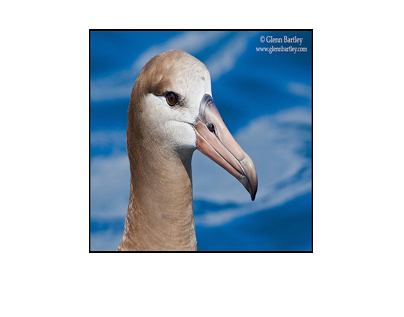

%resizing
targetSize = [224, 224];
training = transform(trainingImageDs, @(x)imresize(x, targetSize));
traininglabel = arrayDatastore(trainingImageDs.Labels);
trainingNet = combine(training, traininglabel);
validation = transform(validationImageDS, @(x)imresize(x, targetSize));
validationlabel = arrayDatastore(validationImageDS.Labels);
validationNet = combine(validation, validationlabel);
test = transform(trainingImageDs, @(x)imresize(x, targetSize));
testLabel = arrayDatastore(testImageDS.Labels);
testNet = combine(test, testLabel);
figure();
imshow(trainingNet.read{1});

%splitting
%[trainingImageDs,validationImageDs] = splitEachLabel(trainingImageDs, 0.6);
%[validationImageDs, testImageDs] = splitEachLabel(validationImageDs, 0.5);

%neural network architecture
layers = [
    imageInputLayer([224 224 3])
    
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(20)
    softmaxLayer
    classificationLayer];

%training options
options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.001, ...
    'MaxEpochs',10, ...
    'Shuffle','every-epoch', ...
    'ValidationData',validationNet, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'MiniBatchSize', 100,...
    'Plots','training-progress');

%clearing old gpu values
if (gpuDeviceCount() > 0)
    disp('Found GPU:');
    disp(gpuDeviceTable);
    device = gpuDevice(1);
    reset(device);  % Clear previous values that might still be on the GPU
end

Found GPU:


    Index        Name        ComputeCapability    DeviceAvailable    DeviceSelected
    _____    ____________    _________________    _______________    ______________

      1      "GRID T4-4Q"          "7.5"               true              true      



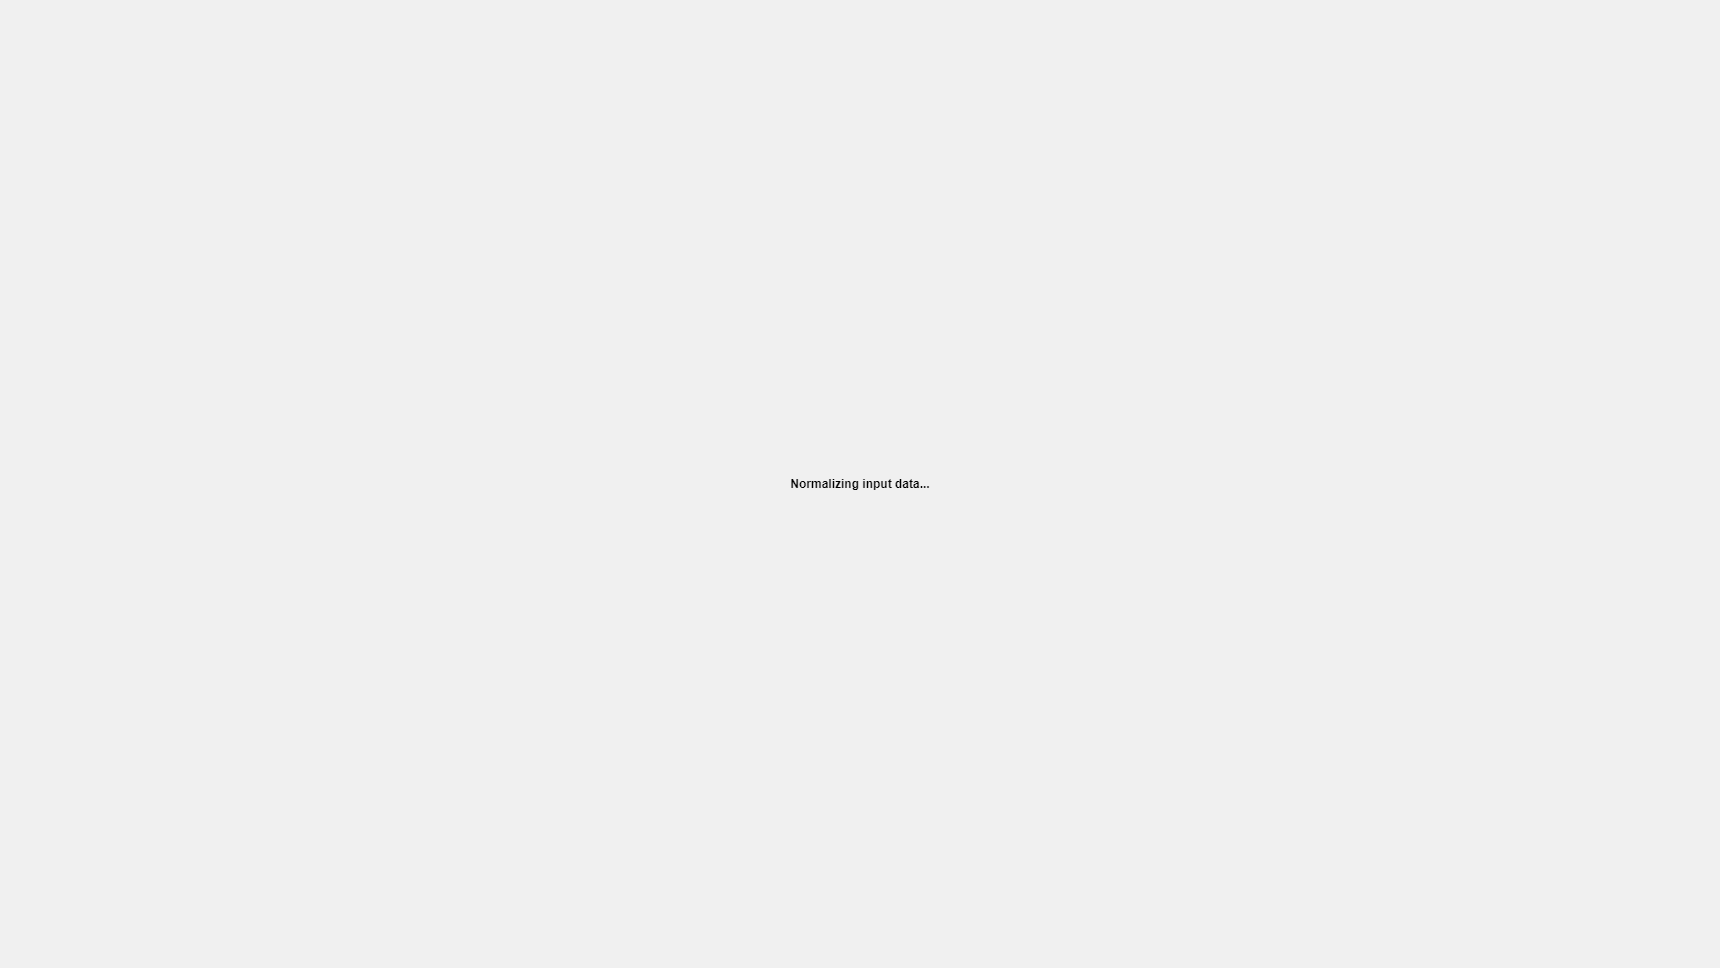

Error using trainNetwork (line 184)
Dimensions of arrays being concatenated are not consistent.

Caused by:
    Error using cat
    Dimensions of arrays being concatenated are not consistent.

% train
net = trainNetwork(trainingNet,layers,options);